平均R²: 0.01


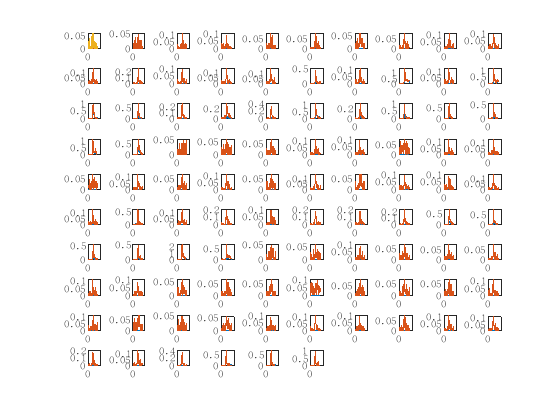

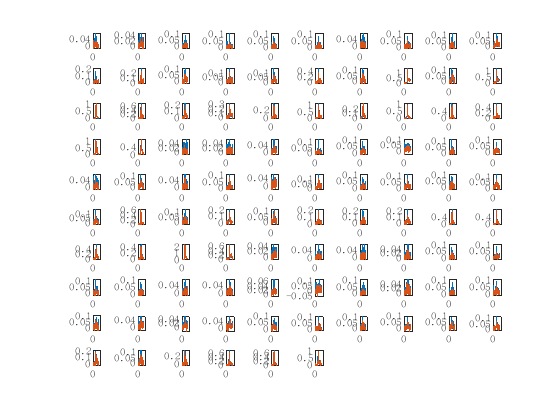

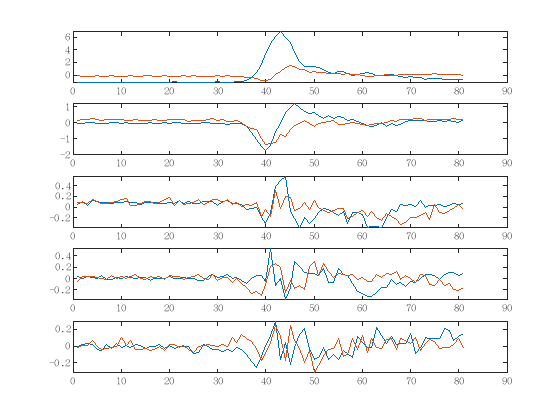

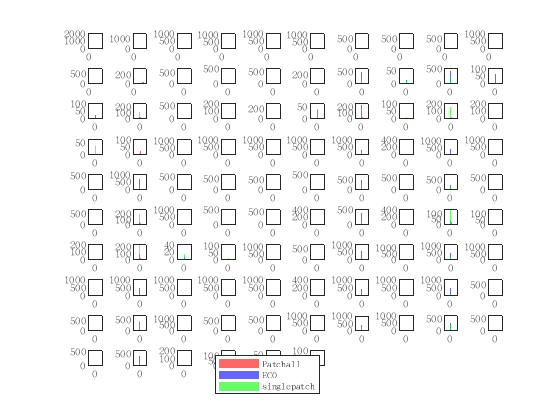

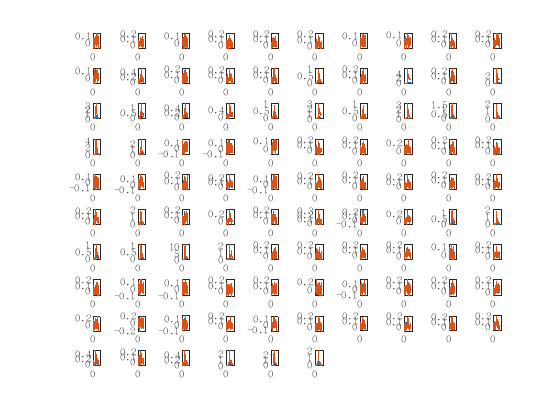

% 假设data的维度为18×89×30×81
for ori = 1:18
    ECdata(ori,:,:,:) = All_data_preEC{1,ori}(1:89,coilselect,:)-mean(All_data_preEC{1,ori}(1:89,coilselect,1:20),3);
end
data = ECdata([5,9,14],:,:,:);
num_orientations = 3;
num_trials = 89;
num_coils = 30;
num_timepoints = 81;

% 初始化存储结果
acc_real = zeros(num_timepoints, 1);
p_values = zeros(num_timepoints, 1);
chance_level = zeros(num_timepoints, 1); % 使用shuffle的95%分位数
nShuffle = 20; % shuffle次数

% 生成标签向量
Y = repelem(1:num_orientations, num_trials)';
for t = 1:num_timepoints
    % 提取当前时间点的数据
    X = reshape(data(:, :, :, t), [], num_coils);
    
    % 交叉验证设置
    cv = cvpartition(Y, 'KFold', 3);
    template = templateSVM('KernelFunction', 'linear', 'Verbose', 0);
    
    % 真实标签的交叉验证分类
    model = fitcecoc(X, Y, 'Learners', template, 'Coding', 'onevsone');
    cvModel = crossval(model, 'CVPartition', cv);
    predicted = kfoldPredict(cvModel);
    acc_real(t) = sum(predicted == Y) / numel(Y);
    
    % Shuffle过程
    acc_shuff = zeros(nShuffle, 1);
    for i = 1:nShuffle
        Y_shuff = Y(randperm(numel(Y)));
        cv_shuff = cvpartition(Y_shuff, 'KFold', 10, 'Stratify', true);
        model_shuff = fitcecoc(X, Y_shuff, 'Learners', template, 'Coding', 'onevsone');
        cvModel_shuff = crossval(model_shuff, 'CVPartition', cv_shuff);
        predicted_shuff = kfoldPredict(cvModel_shuff);
        acc_shuff(i) = sum(predicted_shuff == Y_shuff) / numel(Y_shuff);
    end
    
    % 计算chance level（95%分位数）和p值
    % chance_level(t) = prctile(acc_shuff, 95);
    chance_level(t) = mean(acc_shuff);
    p_values(t) = (sum(acc_shuff >= acc_real(t)) + 1) / (nShuffle + 1);
    disp(t);
end

     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25
    26
    27
    28
    29
    30
    31
    32
    33
    34
    35
    36
    37
    38
    39
    40
    41
    42
    43
    44
    45
    46
    47
    48
    49
    50
    51
    52
    53
    54
    55
    56
    57
    58
    59
    60
    61
    62
    63
    64
    65
    66
    67
    68
    69
    70
    71
    72
    73
    74
    75
    76
    77
    78
    79
    80
    81


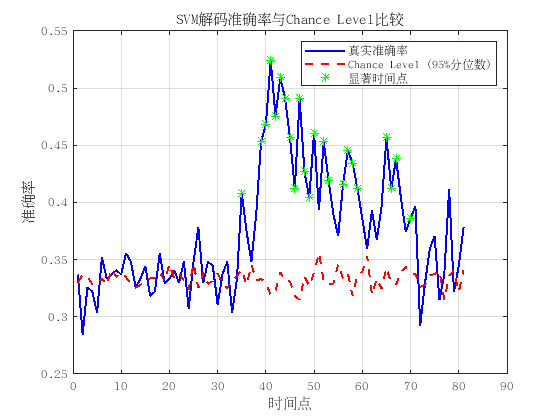

% FDR校正
[h, crit_p, adj_p] = my_fdr_bh(p_values, 0.05);

% 标记显著的时间点
significant_timepoints = find(h);
figure;
plot(1:num_timepoints, acc_real, 'b', 'LineWidth', 1.5);
hold on;
plot(1:num_timepoints, chance_level, 'r--', 'LineWidth', 1.5);
scatter(significant_timepoints, acc_real(significant_timepoints), 'g*');
xlabel('时间点');
ylabel('准确率');
legend('真实准确率', 'Chance Level (95%分位数)', '显著时间点');
title('SVM解码准确率与Chance Level比较');
grid on;

for i = 1:cv.NumTestSets
    trainIdx = training(cv, i);
    testIdx = test(cv, i);
    % 统计训练集和测试集中每个类别的数量
    trainCounts = histcounts(Y(trainIdx), 1:num_orientations+1);
    testCounts = histcounts(Y(testIdx), 1:num_orientations+1);
    disp(['Fold ', num2str(i), ' - Train counts: ', num2str(trainCounts)]);
    disp(['Fold ', num2str(i), ' - Test counts: ', num2str(testCounts)]);
end

Fold 1 - Train counts: 60  59  59  60  59  59  60  59  59


Fold 1 - Test counts: 29  30  30  29  30  30  29  30  30


Fold 2 - Train counts: 59  59  60  59  59  60  59  59  60


Fold 2 - Test counts: 30  30  29  30  30  29  30  30  29


Fold 3 - Train counts: 59  60  59  59  60  59  59  60  59


Fold 3 - Test counts: 30  29  30  30  29  30  30  29  30


function [h, crit_p, adj_p] = my_fdr_bh(p_values, alpha)
    m = length(p_values);
    [sorted_p, sort_idx] = sort(p_values);
    adj_p = zeros(size(sorted_p));
    
    % Benjamini-Hochberg临界值计算
    for i = 1:m
        adj_p(i) = sorted_p(i) * m / i;
    end
    adj_p = min(1, adj_p); % 确保p值不超过1
    
    % 反向调整顺序
    [~, original_order] = sort(sort_idx);
    adj_p = adj_p(original_order);
    
    % 判断显著性
    h = p_values <= alpha;
    crit_p = alpha;
end